# Retrain Neural Network to Classify New Images

This example shows how to retrain a pretrained SqueezeNet neural network to perform classification on a new collection of images.

You can retrain a pretrained network for new datasets by adapting the neural network to match the new task and using its learned weights as a starting point. To adapt the network to the new data, replace the last few layers (known as the network head) so that the neural network outputs prediction scores for each of the classes for the new task. 

There are several techniques to retrain a neural network.

- Retrain from scratch — Train the neural network from scratch using the same network architecture.

- Transfer learning — Freeze the pretrained neural network weights and retrain the network head only.

- Fine-tuning — Retrain some or all of the neural network weights and optionally slow down the training of the pretrained weights.

Transfer learning and fine-tuning a pretrained neural network typically requires less data, is much faster, and is easier than training a neural network from scratch.

This diagram illustrates these retraining workflows.

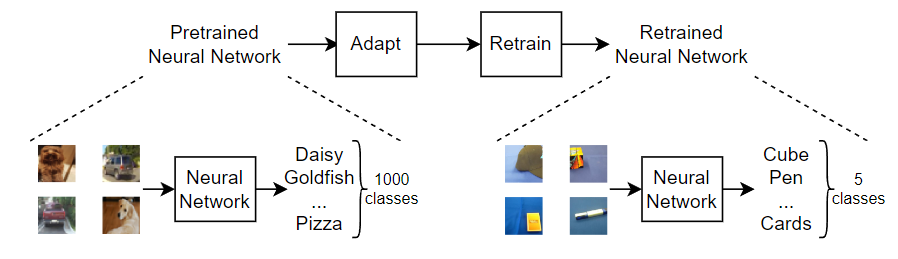

This example retrains a SqueezeNet neural network using transfer learning. This network has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input and outputs a prediction score for each of these classes.

## Load Training Data

Extract the MathWorks Merch dataset. This is a small dataset containing 75 images of MathWorks merchandise, belonging to five different classes (*cap*, *cube*, *playing cards*, *screwdriver*, and *torch*). The data is arranged such that the images are in subfolders that correspond to these five classes.

folderName = "MerchData";
unzip("MerchData.zip",folderName);

Create an image data store. An image datastore enables you to store large collections of image data, including data that does not fit in memory, and efficiently read batches of images during training of a neural network. Specify the folder with the extracted images and indicate that the subfolder names correspond to the image labels.

imds = imageDatastore(folderName, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

Display some sample images.

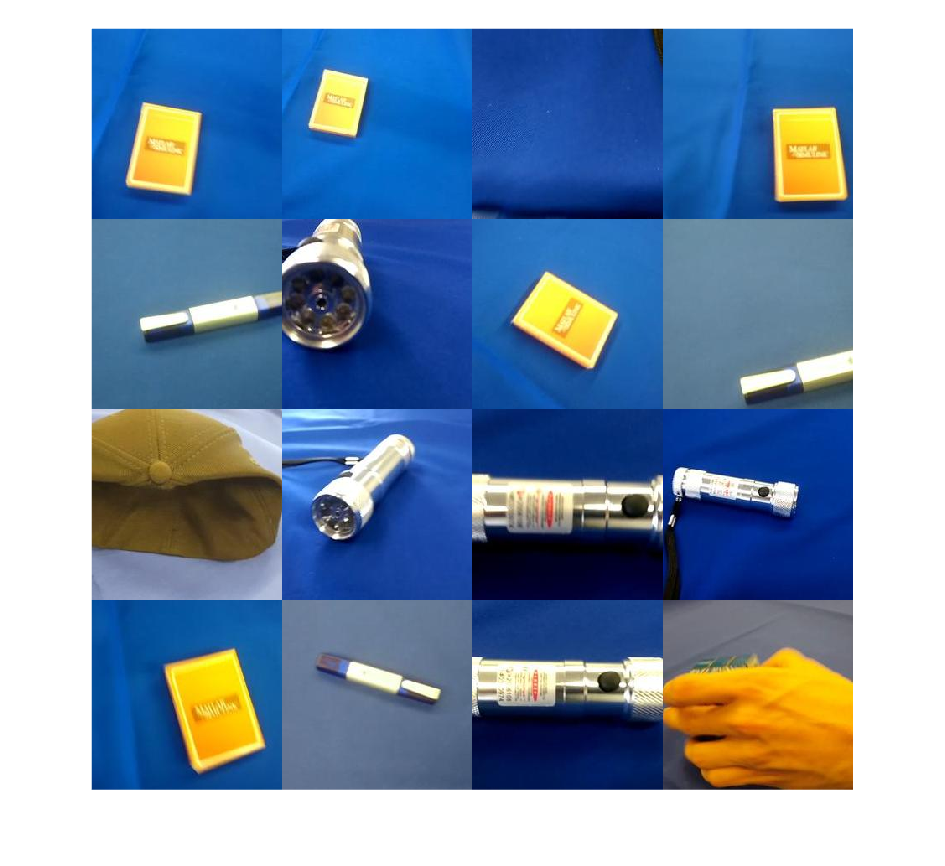

numImages = numel(imds.Labels);
idx = randperm(numImages,16);
I = imtile(imds,Frames=idx);
figure
imshow(I)

View the class names and the number of classes.

classNames = categories(imds.Labels)
numClasses = numel(classNames)

Partition the data into training, validation, and testing datasets. Use 70% of the images for training, 15% for validation, and 15% for testing. The `splitEachLabel` function splits the image datastore into three new datastores.

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,0.7,0.15,"randomized");

## Load Pretrained Network

To adapt a pretrained neural network for a new task, replace the last few layers (known as the network head) so that it outputs prediction scores for each of the classes for the new task. This diagram outlines the architecture of a neural network that makes predictions for $K$ classes and how to edit the network so that it outputs predictions for $K^*$ classes.

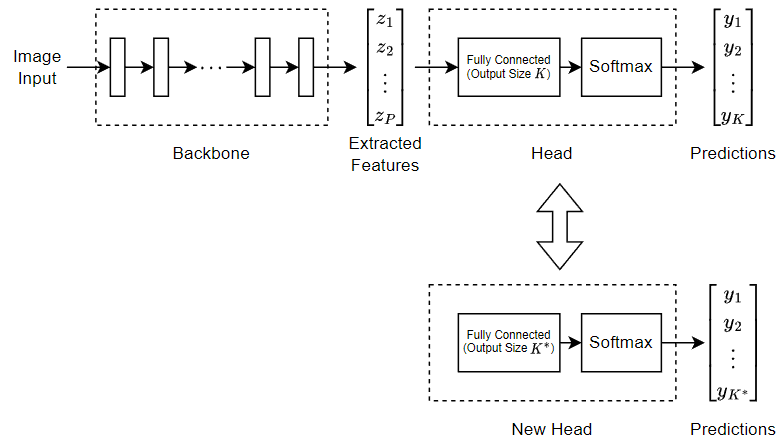

Load a pretrained SqueezeNet neural network using the `imagePretrainedNetwork` function. To return a neural network ready for retraining for the new data, also specify the number of classes. When you specify the number of classes, the `imagePretrainedNetwork` function adapts the neural network so that it outputs prediction scores for each of the specified number of classes.

You can try other pretrained networks. Deep Learning Toolbox™ provides various pretrained networks that have different sizes, speeds, and accuracies. These additional networks require a support package. If the support package is not installed, then the function provides a download link. For more information, see [Pretrained Deep Neural Networks](docid:nnet_ug#bvf9ych-1).

net = imagePretrainedNetwork("squeezenet",NumClasses=numClasses)

View the network architecture, using the `analyzeNetwork` function. Take note of the input layer and the last layer with learnable parameters.

analyzeNetwork(net)

The input layer shows the input size of the neural network.

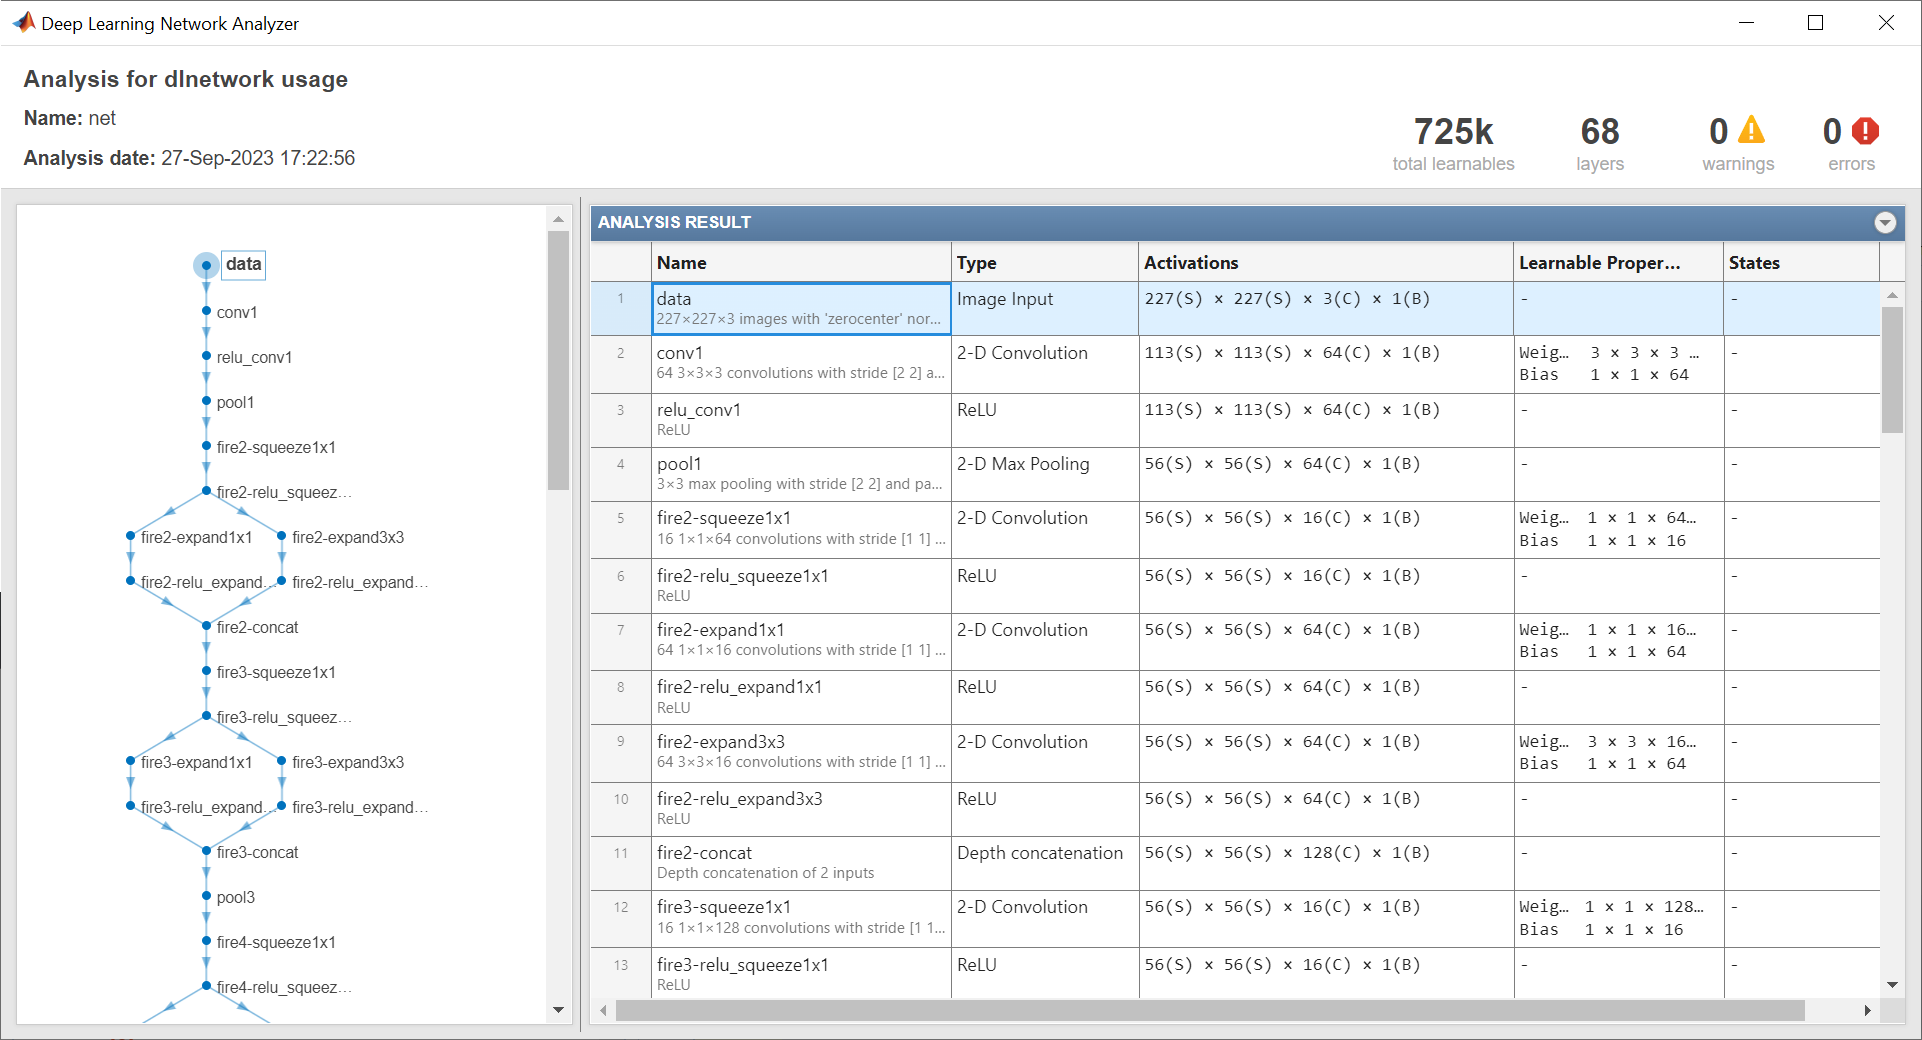

Get the neural network input size from the input layer. The `networkInputSize` function, attached to this example as a support file, extracts the input size from the input layer. To access this function, open the example as a live script.

inputSize = networkInputSize(net)

The learnable layer in the network head (the last layer with learnable parameters) requires retraining. This is usually a fully connected layer or a convolutional layer with an output size that matches the number of classes.

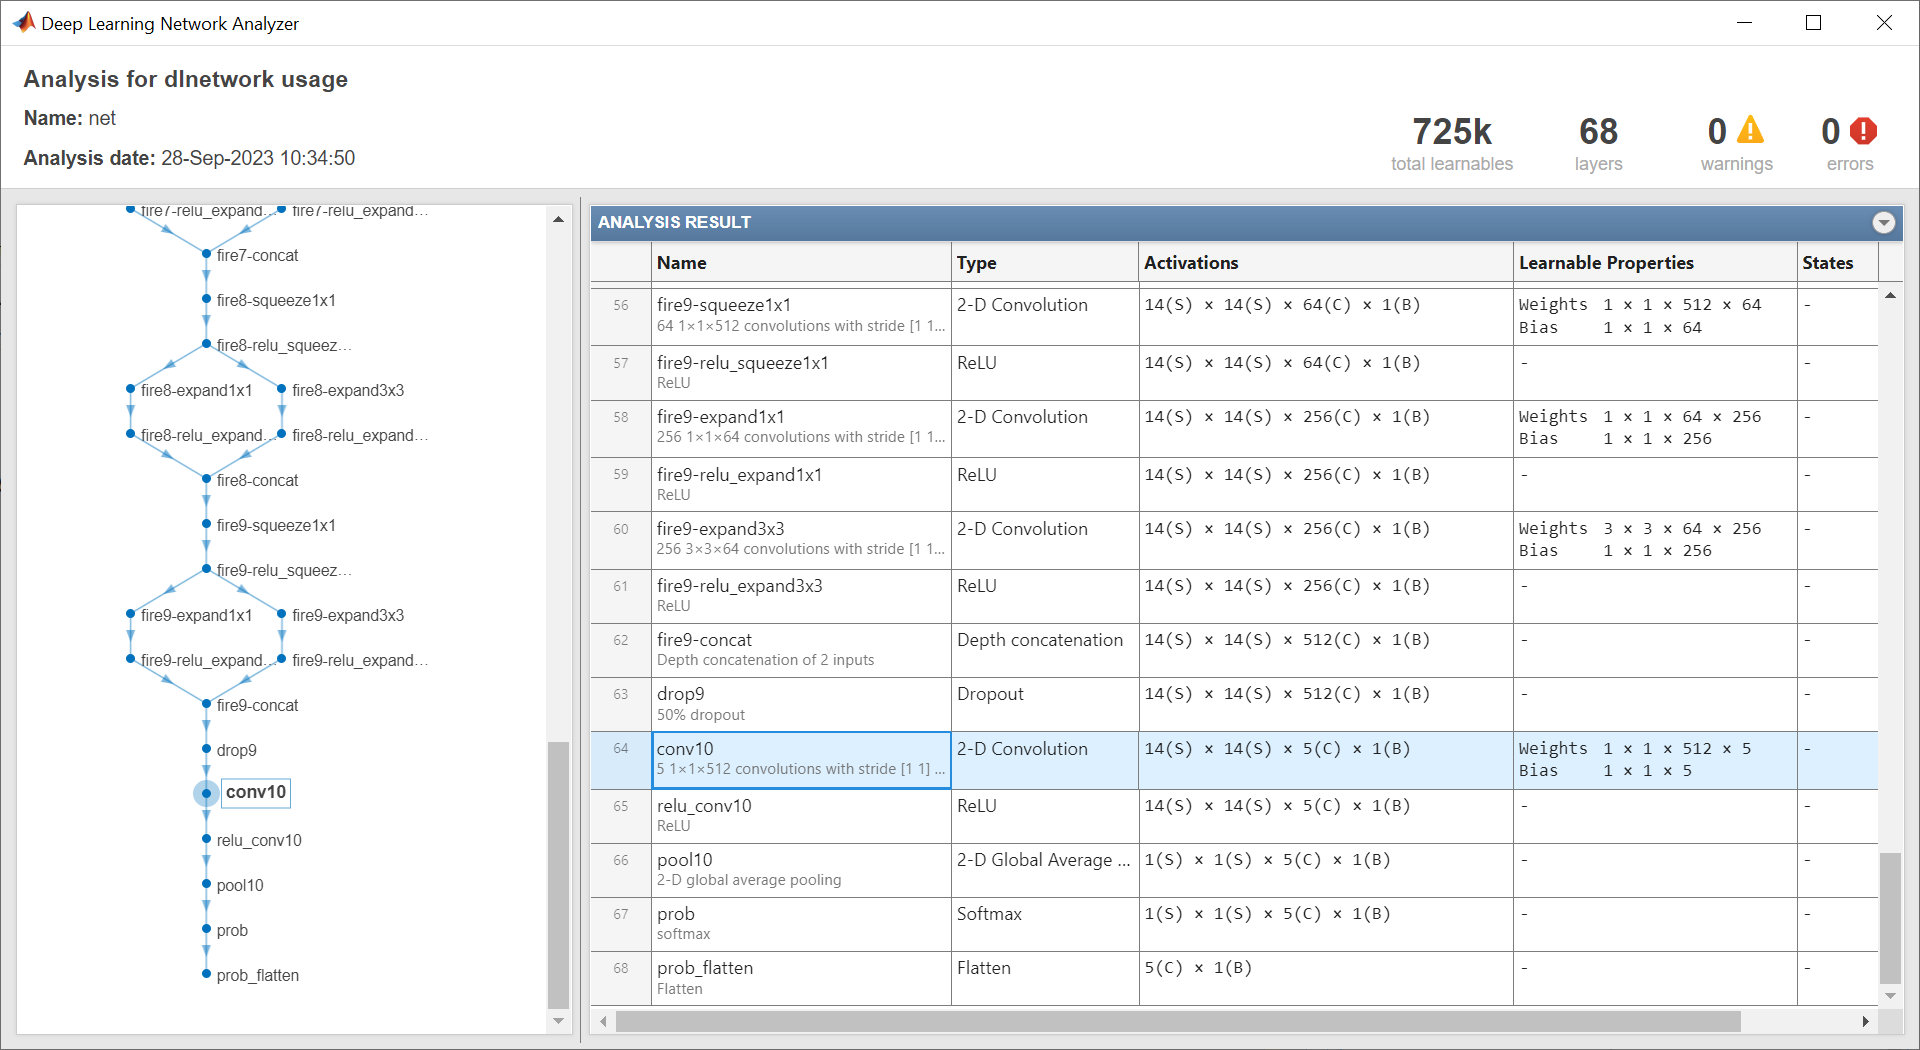

The `networkHead` function, attached to this example as a supporting file, returns the layer and learnable parameter names of the learnable layer in the network head. To access this function, open the example as a live script.

[layerName,learnableNames] = networkHead(net)

For transfer learning, you can freeze the weights of earlier layers in the network by setting the learning rates in those layers to zero. During training, the `trainnet` function does not update the parameters of these frozen layers. Because the function does not compute the gradients of the frozen layers, freezing the weights can significantly speed up network training. For small datasets, freezing the network layers prevents those layers from overfitting to the new dataset.

Freeze the weights of the network, keeping the last learnable layer unfrozen using the `freezeNetwork` function, attached to this example as a supporting file. To access this function, open the example as a live script.

net = freezeNetwork(net,LayerNamesToIgnore=layerName);

**Tip:** As an alternative, instead of freezing the weights of the earlier layers, you can reduce the level of updates to these layers and increase the level of updates to the new classification head. This is known as fine-tuning. To do this, increase the learn rate factors of the learnable parameters in the new classification head using the `setLearnRateFactor` function. Then, decrease the global learning rate using the `InitialLearnRate` training option.

## Prepare Data for Training

The images in the datastore can have different sizes. To automatically resize the training images, use an augmented image datastore. Data augmentation also helps prevent the network from overfitting and memorizing the exact details of the training images. Specify these additional augmentation operations to perform on the training images: randomly flip the training images along the vertical axis, and randomly translate them up to 30 pixels horizontally and vertically. 

pixelRange = [-30 30];

imageAugmenter = imageDataAugmenter( ...
    RandXReflection=true, ...
    RandXTranslation=pixelRange, ...
    RandYTranslation=pixelRange);

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    DataAugmentation=imageAugmenter);

To automatically resize the validation and testing images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

## Specify Training Options

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:matlab_ref.mw_11ce840f-eed7-4975-9c28-baeebd79f092) app.

- Train using the Adam optimizer.

- Validate the network using the validation data every 5 iterations. For larger datasets, to prevent validation from slowing down training, increase this value.

- Display the training progress in a plot and monitor the accuracy metric.

- Disable the verbose output.

options = trainingOptions("adam", ...
    ValidationData=augimdsValidation, ...
    ValidationFrequency=5, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## Train Neural Network

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. For classification, use cross-entropy loss. By default, the `trainnet` function uses a GPU if one is available. Using a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the `trainnet` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

net = trainnet(augimdsTrain,net,"crossentropy",options);

## Test Neural Network

Classify the test images. To make predictions with multiple observations, use the `minibatchpredict` function. To convert the prediction scores to labels, use the `scores2label` function. The `minibatchpredict` function automatically uses a GPU if one is available.

YTest = minibatchpredict(net,augimdsTest);
YTest = scores2label(YTest,classNames);

Visualize the classification accuracy in a confusion chart.

TTest = imdsTest.Labels;
figure
confusionchart(TTest,YTest);

Evaluate the classification accuracy for the test data. The accuracy is the percentage of correct predictions.

acc = mean(TTest==YTest)

## Make Predictions with New Data

Classify an image. Read an image from a JPEG file, resize it, and convert to the single data type.

im = imread("MerchDataTest.jpg");
im = imresize(im,inputSize(1:2));
X = single(im);

Classify the image. To make prediction with a single observation, use the `predict` function. To use a GPU, first convert the data to `gpuArray`.

if canUseGPU
    X = gpuArray(X);
end
scores = predict(net,X);
[label,score] = scores2label(scores,classNames);

Display the image with the predicted label and the corresponding score.

figure
imshow(im)
title(string(label) + " (Score: " + gather(score) + ")")

*Copyright 2023-2024 The MathWorks, Inc.*